# Varmelegeme målinger

T = readtable("varmelegeme_maalinger.xlsx");

## I sekunder

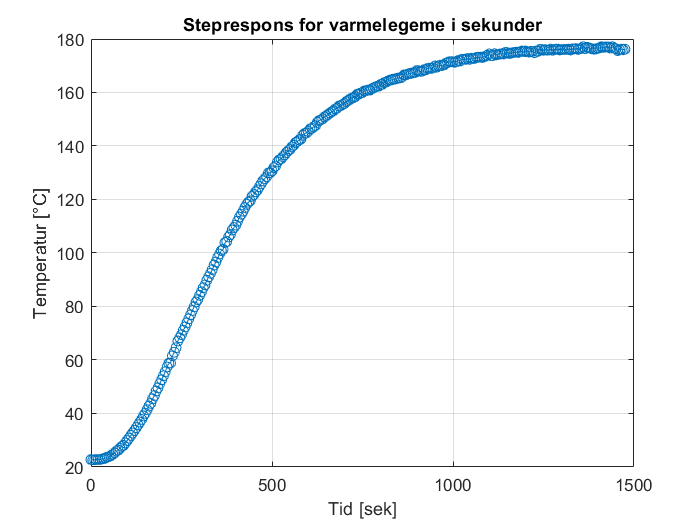

plot(T.Tid60,T.Temp60,'-o')
xlim([0,1500]);
title('Steprespons for varmelegeme i sekunder');
xlabel('Tid [sek]');
ylabel('Temperatur [°C]');
grid on;

## I minutter

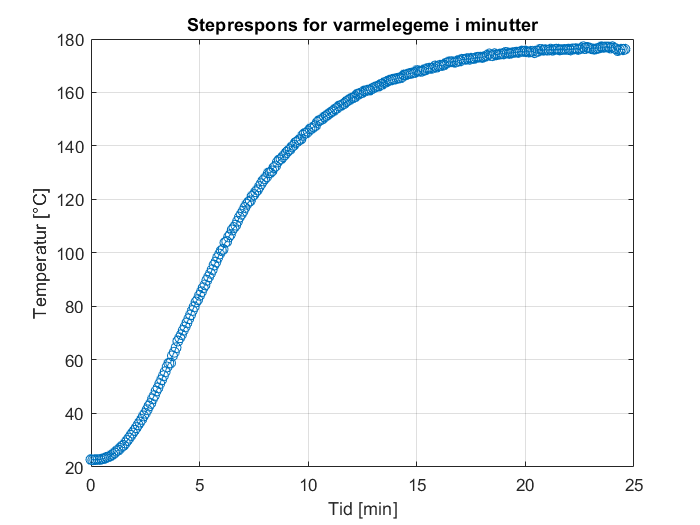

plot((T.Tid60/60),T.Temp60,'-o')
xlim([0,25]);
title('Steprespons for varmelegeme i minutter');
xlabel('Tid [min]');
ylabel('Temperatur [°C]');
grid on;

## Databehandling 60%

Data60 = T.Temp60(1:296);
Tid60 = T.Tid60(1:296);

stepinf60 = stepinfo(Data60,Tid60)

stepinf60 = struct with fields:
        RiseTime: 622.6923
    SettlingTime: 1.0808e+03
     SettlingMin: 160.9000
     SettlingMax: 177.1000
       Overshoot: 0.5108
      Undershoot: 0
            Peak: 177.1000
        PeakTime: 1360


settl60 = round(stepinf60.SettlingTime/5)*5;
settlss60 = Data60(settl60/5:296);
steadystate60 = mean(settlss60)

steadystate60 = 175.6370

## Databehandling 70%

Data70 = T.Temp70(1:256);
Tid70 = T.Tid70(1:256);

stepinf70 = stepinfo(Data70,Tid70)

stepinf70 = struct with fields:
        RiseTime: 577.3273
    SettlingTime: 949.4545
     SettlingMin: 182.5000
     SettlingMax: 200
       Overshoot: 0
      Undershoot: 0
            Peak: 200
        PeakTime: 1035


settl70 = round(stepinf70.SettlingTime/5)*5;
settlss70 = Data70(settl70/5:255);
steadystate70 = mean(settlss70)

steadystate70 = 199.3045

## Sammenligning af data målinger

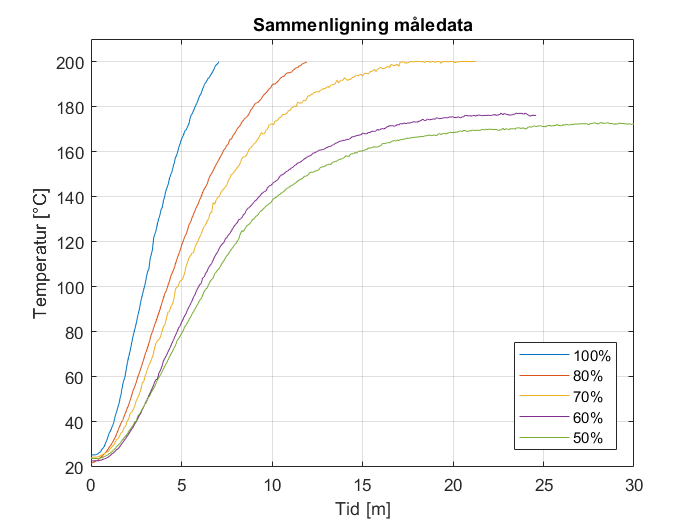

plot((T.Tid100)/60,T.Temp100);
hold on; grid on;
plot((T.Tid80)/60,T.Temp80);
plot((T.Tid70)/60,T.Temp70);
plot((T.Tid60)/60,T.Temp60);
plot((T.Tid50)/60,T.Temp50);
title('Sammenligning måledata');
xlim([0 30]);
ylim([20 210]);
xlabel('Tid [m]');
ylabel('Temperatur [°C]');
legend('100%','80%','70%','60%','50%','Location',"best");
hold off;

## Steady-State forudsigelse

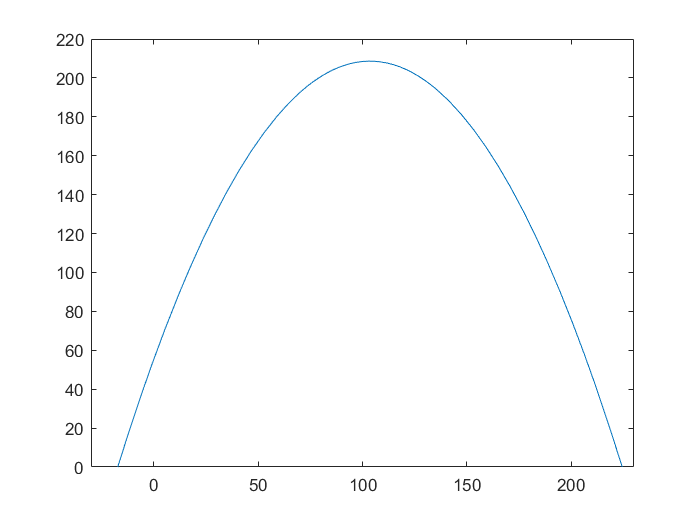

syms x;
y = (-0.0143*x^2)+(2.9623*x)+(55.205); % Tendens fra Excel

fplot(y)
xlim([-30 230])
ylim([0 220])


h = eval(solve(diff(y)== 0));

max = eval(subs(y,x,h))

max = 208.6180

## Overføringsfunktion

% 60 DUTY CYCLE
Gain_pande60 = steadystate60;
delay_pande60 = 20;
offset = T.Temp60(delay_pande60/5)

offset = 22.8000

taun60 = 0.63*(steadystate60-offset)

taun60 = 96.2873

tau60 = 345-delay_pande60

tau60 = 325

tf('s');
sys60 = tf([Gain_pande60*1/tau60],[tau60 1])


sys60 =
 
   0.5404
  ---------
  325 s + 1
 
Continuous-time transfer function.




%step(sys60)

% 70 DUTY CYCLE
Gain_pande70 = steadystate70;
delay_pande70 = 0;
offset = T.Temp70(1)

offset = 24

taun70 = 0.63*(steadystate70-offset)

taun70 = 110.4419

tau70 = 320-delay_pande70

tau70 = 320

tf('s');
sys70 = tf([Gain_pande70*1/tau70],[tau70 1])


sys70 =
 
   0.6228
  ---------
  320 s + 1
 
Continuous-time transfer function.




%step(sys70)
 

%sys707 = tf([Gain_pande70*1/tau70],[tau70 1])
%step(sys707)